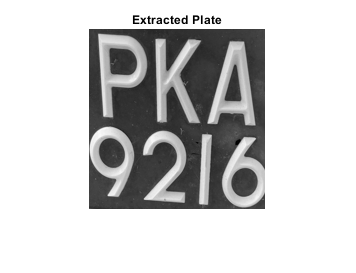

I = rgb2gray(imresize(imread("Plate9.jpg") , [512,512]));

Icrop = imcrop(I , [128 128 256 384]);
corners = detectHarrisFeatures(Icrop);

strongestCorner = corners.selectStrongest(30); 
TF = rmoutliers(strongestCorner.Location,'median');
 
X = min(TF(:,1));
Y = min(TF(:,2));
h = max(TF(:,2)) - Y ;
w = max(TF(:,1)) - X ;

new= imcrop(Icrop , [X-10  Y-5  w+20 h+10]);
figure,imshow(new);title("Extracted Plate");

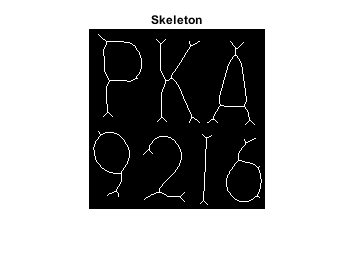


Iafter = imcomplement(imbinarize(uint8(new)));
skel = bwmorph(imcomplement(Iafter),'skel',Inf);
figure,imshow(skel);title("Skeleton"); 

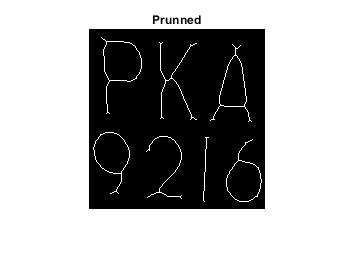

prunned = bwmorph(skel , "spur" , 3);
figure,imshow(prunned);title("Prunned");

% If got two rows then split it in half and join it back with the first row
[w h] =size(prunned); 
se2 = strel('rectangle' , [4,600]);
d = h-w 

d = -4

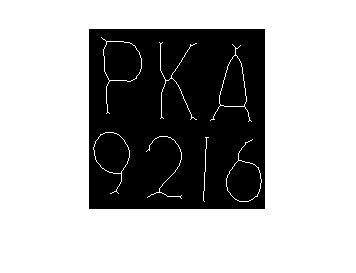

if d <= 25
    imshow(prunned);
    [character_head, character_width] = getLump(prunned, 1);
end

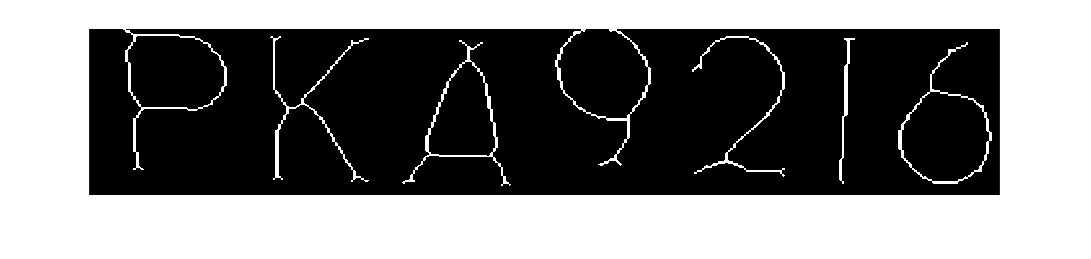


Image = [] ;
for i = 1:length(character_head)
    [k w] = size(prunned);  
    X = 0;
    Y = character_head(i);
    h = character_width(i);
    im = imcrop(prunned , [X Y w h]);
    im = imresize(im, [400 1100]);
    Image = [Image {im}]; 
    %subplot(1,length(character_head) ,i ), imshow(mat2gray(im));
end
a = montage(Image , 'Size', [1 2]);

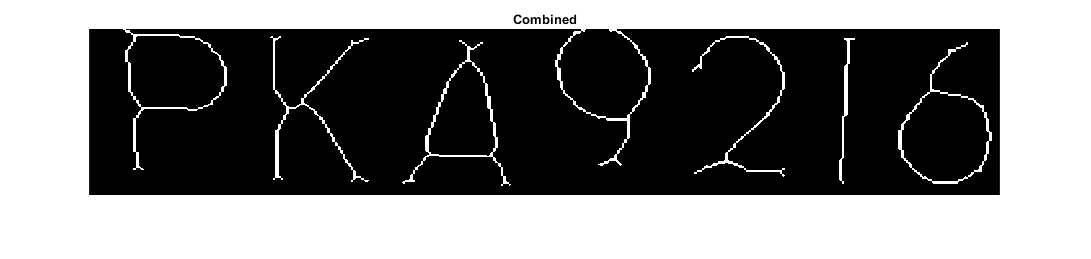

a = a.CData;
a = ~logical(a); 
imshow(imcomplement(a));title("Combined");


[character_head,character_width] = getLump(prunned , 0); 

for i = 1:length(character_head)
    [h z] = size(prunned);  
    X = character_head(i);
    Y = 0;
    w = character_width(i);
    im = imcrop(prunned , [X-2 Y w+2 h]);
    im = imresize(im, [1200 500]);
    subplot(1,length(character_head) ,i ), imshow(mat2gray(im));
end


dir == 1 means row by row 

dir == 0  means column by column 

function [character_head, character_width] = getLump(prunned, dir)
    sh = prunned;
    [m,n] = size(sh);
    if dir  
        se2 = strel("rectangle" , [4,600]); 
        sh = padarray(sh,[2,0], "pre"); 
        loop_row_column = m;
    else 
        se2 = strel('rectangle' , [160,2]); 
        sh(1:m,1:3) = 0 ; 
        loop_row_column = n;
    end
    for k=1:1
        sh =  imdilate(sh,se2);
    end 
    i = 1 ;
    head = 0 ;
    tail = 0 ;
    character_head = [];
    character_width = [] ; 
    while i < loop_row_column
        if dir  
            cur_val = sh(i,n);
            prev_val = sh(max([1,i-1]) , n);
        else 
            cur_val = sh(m,i);
            prev_val = sh(m, max([1,i-1]) );
        end
        if head == 0  
            if cur_val ~= prev_val 
                head = i ;
            else
                i = i +1 ;
            end
        else
            if head ~= 0 && tail == 0 
                if cur_val == 1 
                    i = i + 1;
                else 
                    tail = i;
                    character_head = [character_head , head]; 
                    character_width = [character_width , tail-head];
                    i = i + 1 ; 
                    head = 0 ; 
                    tail = 0 ;
                end
            else
                i = i + 1; 
                head = 0 ; 
                tail = 0 ; 
            end
        end
    end
end